clear

%Maths assignment Semester 1 2020
%Name:Jack Cornwall
%Student Number: C0037685
%Date: 17.11.20

%Question 1
%Validate answer calculated manually

%declaring symbolic variables
syms f(r) df(r) df_calc(r);

%declaring function
f(r) = r^2 * log(1/r);

%differentiating function with respect to r
df(r) = diff(f(r), r)

$$df(r) = 2\,r\,\log\left(\frac{1}{r}\right)-r$$


%declaring manually calculated derivative
df_calc(r) = -r*(1+2*log(r));

%setting constraints as defined by question
assume(r>0 & r<=1);

%checking functions match
isAlways(simplify(df_calc(r) == df(r)))

ans = logical
   1



%ensuring functions are identical
simplify(df_calc(r) - df(r))

$$ans = 0$$

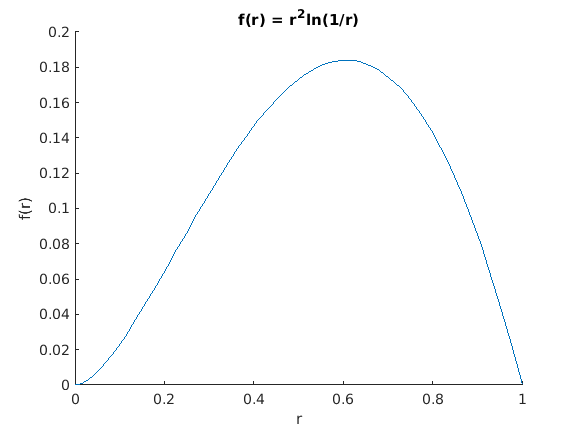


%plotting function between required x limits
fplot(f(r), [0 1])
ylim([0 .2])


%beautifying plot
ax=gca;
ax.YAxisLocation="origin";
ax.XAxisLocation="origin";
box off

%labelling graph
xlabel("r")
ylabel("f(r)")
title("f(r) = r^{2}ln(1/r)")

hold off %ensuring a new plot is started


%plotting function between required x limits
fplot(f(r), [0 1])
ylim([0 .2])

%beautifying plot
ax=gca;
ax.YAxisLocation="origin";
ax.XAxisLocation="origin";
box off

%labelling graph
xlabel("r")
ylabel("f(r)")
title("f(r) = r^{2}ln(1/r)")

hold on %ensuring new lines are plotted on same graph
fplot(0.18, [0 1],"g") %plotting y line
xline(0.6,'r') %plottign x line

r_1 = exp(-1/2) %value of r at turning point

r_1 = 0.6065

f_1 = eval(f(r_1)) %value of f(r) at turning point

f_1 = 0.1839


solve(df(r) == 0, r) %solving for turning points between 0 & 1

$$ans = {\mathrm{e}}^{-\frac{1}{2}}$$


eval(ans) %stating the answer (4 d.p.)

ans = 0.6065


%calculating y coordinate for previously calculated r value
eval(f(ans))

ans = 0.1839

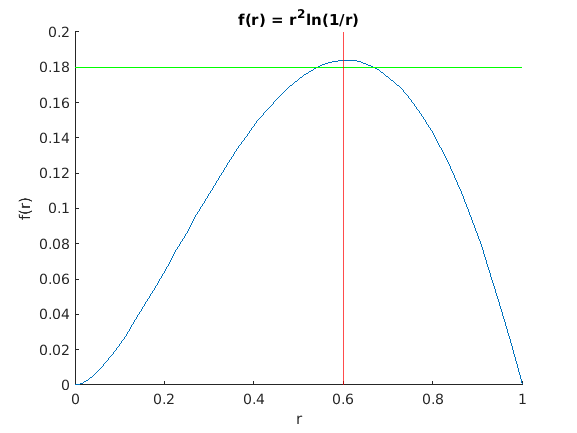


hold off

%question 2 part a
clear
%declaring symbolic variables
syms v(t) dV(t)


T = (9/80) - (1/80); %calculating period
w = (2*pi)/T; %calculating angular frequency
p = pi/4; %declaring phy
K = 4; %declaring amplitude K

%setting up equation
v(t)=K*sin(w*t + p);

%checking turning points, match what we are given
dV(t) = diff(v(t), t); %differentiating
assume(t>0 & t<0.2); %suggesting sensible limits
solve(dV(t)==0, t) %calculating turning points

%solving for our turning points
eval(v(1/80))
eval(v(9/80))

%further solving for troughts (expecing -4 as answer rather than 4)
eval(v(1/16))
eval(v(13/80))

%checking calculated values of phi
sin (pi/4)
sin((-7*pi)/4)

%plotting function between required x limits
fplot(v(t), [0 .2])
ylim([-4.2 4.2])

%beautifying plot
ax=gca;
ax.YAxisLocation="origin";
ax.XAxisLocation="origin";
box off

%labelling graph
xlabel("t [seconds]")
ylabel("V [Voltage]")
title("Sinusoidal wave form V(t) = Ksin(\omegat + \phi)")

hold off

%question 2 part b
clear

%declaring symbolic functions and variables
syms i(t)

i(t) =12*sin(100*pi*t - pi/8); % declaring sinusoidal function

%setting a sensible range for t (using the period)
assume(t>0 & t<0.02)

eval(solve(i(t)==-6,t))

ans =     0.0129
    0.0196



fplot(i(t), [0,0.02])
ylim([-12.5 12.5])

%beautifying plot
ax=gca;
ax.YAxisLocation="origin";
ax.XAxisLocation="origin";
box off

%labelling graph
xlabel("t [seconds]")
ylabel("i [mA]")
title("Current over time i(t) = 12sin(100\pit - \pi/8)")

T = (2*pi)/(100*pi)

T = 0.0200

tq= T/8

tq = 0.0025


-1/2400 + 8*tq

ans = 0.0196

eval(i(ans))

ans = -6

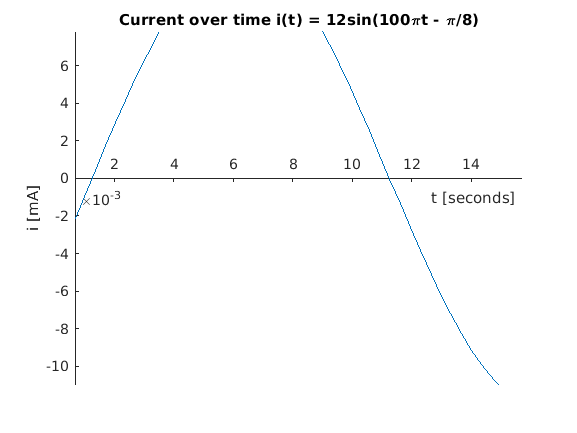


hold off

%question 3
clear

syms y(x) y_sq(x) y_sq_2(x) y_int

%declaring variables
R=0.1;
L=2/5;
K=1;

%declaring equation
y(x) = (R/(2-K))*((2/L)*x - (K/L^2)*x^2)

$$y(x) = \frac{x}{2}-\frac{5\,x^{2}}{8}$$


%plotting graph for given ranges of x
fplot(y, [0 L])

axis equal %ensures axis scales are equal
ylim([0 0.12]) %setting y lim, this needs to be done after axis equal command to work

box off

%adding labels and title to curve
xlabel("Length [m]")
ylabel("Height [m]")
title("Top half of nosecone outline in 2 d")

%declaring y squared to then be integrated
y_sq(x) = simplify(y(x)^2)

$$y\_sq(x) = \frac{x^{2}\,{\left(5\,x-4\right)}^{2}}{64}$$


%comparing pen and paper to MATLAB "squaring" of y(x)
y_sq_2(x) = simplify((1/64)*(16*x^2 - 40*x^3 +25*x^4))

$$y\_sq\_2(x) = \frac{x^{2}\,{\left(5\,x-4\right)}^{2}}{64}$$

isAlways(y_sq_2(x) == y_sq(x)) % the results match

ans = logical
   1



%integrating y^2 from 0 to L (0.4m)
eval(int(y_sq(x),x,0,.4))

ans = 0.0021


%calculating volume of nose cone
V_nose_cone = ans*pi

V_nose_cone = 0.0067


%checking entire integral in one step
V_nose_cone_check = eval(pi*int((y(x))^2,x,0,.4))

V_nose_cone_check = 0.0067


%calculating volumne of cone denoted by points:
%(0,0), (0.4,0) and (0.4,0.1) & rotated about x-axis
r=0.1

r = 0.1000

h=0.4

h = 0.4000

V_cone = (pi*(r^2)*h)/3

V_cone = 0.0042


%calculating volume of cylinder denoted by points:
%(0,0), (0.4,0), (0.4,0.1) and (0,0.1) & rotated about x-axis
V_cylinder = (pi*(r^2)*h)

V_cylinder = 0.0126

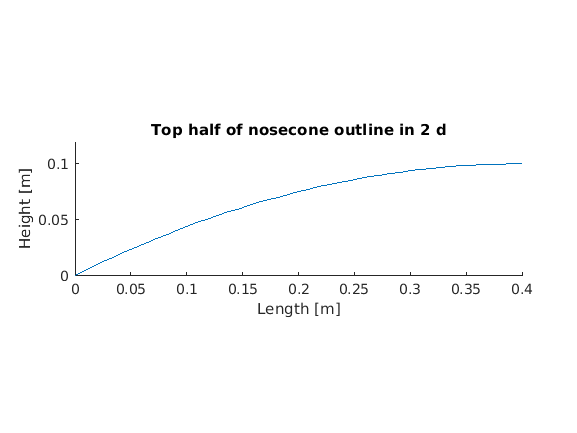


hold off